# Training Neural Networks for Spectrogram-Based Signal Classification

The following LiveScript trains a Neural Network of the users choice to perform segmentation on spectrograms images of given size and to calssify signals in the ISM (Industrial Scientific Medical) frequency band (2.4 GHz).

### Parameters Choice 

The following parameters can be customized by the user to train their own Net.

- ***netChoice*****: **The user can choose the NN to train between U*Net *and *deepLabV3+*

- ***encoderChoice: ***Select *ResNet18 *for a faster and lighter net, *ResNet50 *to utilize a more complex encoder

- ***useAttentionGates: ***select wheter to customize the net with AttentionGates (Note: while this can lead to performance increase, it will also slow both training and inference processes)

- ***execEnv:*** select the environment where to execute your operations on (if available, GPU or Multi-GPU is recommended)

Other fine tuning parameters include 

- **initialLearnRate: **initial learning rate for the net 

- **maxEpochs: **number of epochs after which training is stopped

- **miniBatchSize: **size of batches for training purposes

#### Note: other parameters can be changed later in the script, however for consistency with our experiments we do not recommend to edit them. To learn about our choice of parameters, please refer to the technical report.

netChoice          = "unet";      % "unet" | "deeplab"
encoderChoice      = "resnet18";  % "resnet18" | "resnet50"
useAttentionGates  = true;        % true | false  (only used with UNet)

execEnv            = "cpu"; % "gpu" | "multi-gpu" | "cpu" | "auto"

initialLearnRate   = 0.0008;
maxEpochs          = 25;
miniBatchSize      = 32;

checkpointDir      = fullfile(pwd, "checkpoints");
outputDir          = fullfile(pwd, "trainedNets");
if ~exist("checkpointDir", "dir")
    mkdir(checkpointDir);
end

if ~exist("outputDir", "dir")
     mkdir(outputDir);
end

The folder "*checkpoints/*" is used to save the net's checkpoints during training, while "*trainedNets/*" is where the completed net and related info are saved.

close all; clc; clearvars -except netChoice encoderChoice useAttentionGates execEnv ...
                               initialLearnRate maxEpochs miniBatchSize ...
                               checkpointDir outputDir;

### Dataset Definition

The net can be trained on a dataset composed of *.png *files for images and *.mat *matrixes of equal sizes for the labels.

To generate the datasets (some of which can be found in **ADDFOLDERWHEREWEUPLOADDATASET**) we used our own 

function, which synthetically generates, labels and saves spectrograms of common signals found in the ISM band according to the following table.

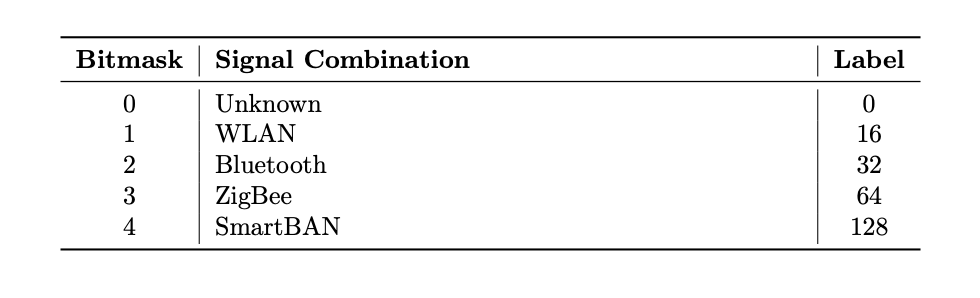

#### More information can be found in the creatingTrainingImages LiveScript

% **** DO NOT TOUCH THESE FIELDS! ****
numClasses  = 5;
classNames  = ["Unknown", "WLAN", "ZigBee", "Bluetooth", "SmartBAN"];
pixelLabelID = uint8([0 16 32 64 128]);   % values stored in .mat label masks

Select the path of the folder where the images used for training are saved.

% Folder that contains PNG images and matching .mat masks (same filename)
dataFolder = fullfile(pwd,"trainingImages","256x256");
if ~exist(dataFolder, "dir")
    error("Folder does not exist. Be sure to have the folder with the dataset!");
end

Then use 

To generate the **ImageDatastore** object to be used for training, validation and testing, toghether with **pixelLabelDatastore**.

The two objects are then combined toghether for faster access.

% --- imageDatastore for PNG spectrograms
imds = imageDatastore(dataFolder, ...
    FileExtensions=".png", IncludeSubfolders=false);

% --- pixelLabelDatastore for bit‑mask labels stored as .mat files
matFiles  = dir(fullfile(dataFolder, "*.mat"));
matPaths  = fullfile({matFiles.folder}, {matFiles.name})';

pxds = pixelLabelDatastore(matPaths, ...
    classNames, pixelLabelID, ...
    ReadFcn=@readGroundTruthMatFile, ...
    FileExtensions=".mat");

% --- Combine (image, label) pairs into a single datastore for fast I/O
pximds = pixelLabelImageDatastore(imds, pxds);

The Datastore object is then partitioned between **Training**, **Validation **and **Testing**. While the sizes of the respective portions can be changed, we recommend keeping the partition [ 0.7 0.1 0.2 ] and if necessary increase the amount of images in the dataset.

[imdsTrain, pxdsTrain, imdsVal, pxdsVal, imdsTest, pxdsTest] = ...
    helperSpecSensePartitionData(imds, pxds, [70 10 20]);
cdsTrain = combine(imdsTrain, pxdsTrain);
cdsVal   = combine(imdsVal,   pxdsVal);
cdsTest  = combine(imdsTest,  pxdsTest);

The partitions are seeded for reproducibility.

### Building the Network

In the following section we build the **lgraph **object based on the choices made by the user.

It's important that **inputSize **matches the sizes of the images used for training.

inputSize = [256 256 3];   % spectrogram tile size

switch lower(netChoice)
    case "unet"
        % --- Build UNet backbone with selected ResNet encoder
        [encNet, ~] = pretrainedEncoderNetwork(encoderChoice, 4);
        lgraph = unet(inputSize, numClasses, ...
            "EncoderNetwork",  encNet, ...
            "EncoderDepth",    4);

        % Optionally enhance skip connections with Attention Gates
        if useAttentionGates
            skipLayers   = ["encoderDecoderSkipConnectionCrop4", ...
                           "encoderDecoderSkipConnectionCrop3", ...
                           "encoderDecoderSkipConnectionCrop2", ...
                           "encoderDecoderSkipConnectionCrop1"];
            gateLayers   = ["Decoder-Stage-4-UpConv", ...
                           "Decoder-Stage-3-UpConv", ...
                           "Decoder-Stage-2-UpConv", ...
                           "Decoder-Stage-1-UpConv"];
            concatLayers = ["encoderDecoderSkipConnectionFeatureMerge4", ...
                           "encoderDecoderSkipConnectionFeatureMerge3", ...
                           "encoderDecoderSkipConnectionFeatureMerge2", ...
                           "encoderDecoderSkipConnectionFeatureMerge1"];
            for i = 1:numel(skipLayers)
                lgraph = addAttentionGate(lgraph, skipLayers(i), gateLayers(i), ...
                                           concatLayers(i), "att"+i);
            end
        end

    case "deeplab"
        % --- DeepLab v3+ with selectable encoder
        lgraph = deeplabv3plus(inputSize, numClasses, encoderChoice);
        % (DeepLab already uses an ASPP head; attention gates optional here)
    case "trained"
        load("myTrainedNet.mat","lgraph");

    otherwise
        error("Unknown netChoice '%s'. Use 'unet' or 'deeplab'.", netChoice);
end

Before training the net, the **trainingOptions **are set as following

options = trainingOptions("adam", ...
    InitialLearnRate      = initialLearnRate, ...
    LearnRateSchedule     = "piecewise", ...
    LearnRateDropFactor   = 0.1, ...
    LearnRateDropPeriod   = 10, ...
    MaxEpochs             = maxEpochs, ...
    MiniBatchSize         = miniBatchSize, ...
    Shuffle               = "every-epoch", ...
    ValidationData        = cdsVal, ...
    ValidationFrequency   = 50, ...
    VerboseFrequency      = 50, ...
    Plots                 = "training-progress", ...
    CheckpointPath        = checkpointDir, ...
    CheckpointFrequency   = 1, ...
    ExecutionEnvironment  = execEnv);

### Training and Performance Evaluation

After building the net, it's time to train it and evaluate the performances. The training process saves every epoch so that no progress is lost in case of crash or sudden interruption. 

When the net is done training, both the net and the training information are saved, after which the evaluation of the net on the testing partition of the dataset begins.

[net, trainInfo] = trainnet(cdsTrain, lgraph, "crossentropy", options);

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _________    _____    ___________    _________    ____________    ______________
            0        0       00:01:01       0.0008                            1.8221
            1        1       00:01:02       0.0008             1.8                  


Training stopped: Training interrupted



timeTag = datetime("now", "yyyy_mm_dd_HH_MM_SS");
save(fullfile(outputDir, "net_"+timeTag+".mat"),       "net",       "-v7.3");
save(fullfile(outputDir, "trainInfo_"+timeTag+".mat"), "trainInfo", "-v7.3");


The following is the code used for performance evaluation. If needed, a *net *variable can be loaded to evaluate a pre-trained network.

pxdsResults = semanticseg(imdsTest, net, ...
    MinibatchSize = miniBatchSize, ...
    WriteLocation = tempdir, ...
    Classes       = classNames);

metrics = evaluateSemanticSegmentation(pxdsResults, pxdsTest);
figure; confusionchart(metrics.ConfusionMatrix.Variables, classNames, ...
    Normalization="row-normalized", ...
    Title="Confusion Matrix – Test Set");

disp(metrics.DataSetMetrics);

disp("\n**************** Training & Evaluation complete ****************");

### Helper Functions

%% helperSpecSensePartitionData : consistent 70/10/20 split ---------------
function [imdsTr, pxdsTr, imdsVa, pxdsVa, imdsTe, pxdsTe] = ...
        helperSpecSensePartitionData(imds, pxds, parts)
%  Borrowed from Mathwork's code
%   Copyright 2021-2023 The MathWorks, Inc.
% helperSpecSensePartitionData - Partition image and pixel label datastores into training, validation, and test sets.
%
% Syntax:
%   [imdsTr, pxdsTr, imdsVa, pxdsVa, imdsTe, pxdsTe] = ...
%       helperSpecSensePartitionData(imds, pxds, parts)
%
% Description:
%   This helper function randomly partitions a paired image datastore (`imds`) and
%   pixel label datastore (`pxds`) into training, validation, and test subsets
%   according to the specified percentage splits.
%
% Inputs:
%   imds   - ImageDatastore containing input images.
%   pxds   - PixelLabelDatastore containing corresponding pixel labels.
%   parts  - 1x3 numeric vector specifying [train, val, test] split percentages.
%            The values must sum to 100.
%
% Outputs:
%   imdsTr - ImageDatastore for training.
%   pxdsTr - PixelLabelDatastore for training.
%   imdsVa - ImageDatastore for validation.
%   pxdsVa - PixelLabelDatastore for validation.
%   imdsTe - ImageDatastore for testing.
%   pxdsTe - PixelLabelDatastore for testing.
%
% Notes:
%   - Random seed is fixed (rng(0)) for reproducibility.
%   - The number of images in each split is computed using `floor`, so the total
%     number of samples in the output may be slightly less than the original dataset.
%
% Example:
%   [imdsTr, pxdsTr, imdsVa, pxdsVa, imdsTe, pxdsTe] = ...
%       helperSpecSensePartitionData(imds, pxds, [70 15 15]);

    % parts = [train  val  test] as percentage (must sum to 100)
    validateattributes(parts, {'numeric'}, {'size', [1 3]});
    assert(sum(parts)==100, "Sum of parts must be 100");

    rng(0);                 % reproducibility
    numFiles = numel(imds.Files);
    idx      = randperm(numFiles);

    nTrain   = floor(numFiles*parts(1)/100);
    nVal     = floor(numFiles*parts(2)/100);

    imdsTr = subset(imds, idx(1:nTrain));
    imdsVa = subset(imds, idx(nTrain+(1:nVal)));
    imdsTe = subset(imds, idx(nTrain+nVal+1:end));

    pxdsTr = subset(pxds, idx(1:nTrain));
    pxdsVa = subset(pxds, idx(nTrain+(1:nVal)));
    pxdsTe = subset(pxds, idx(nTrain+nVal+1:end));
end


%% readGroundTruthMatFile : parses bitmask matrices -----------------------
function mask = readGroundTruthMatFile(filename)
    % Assumes each .mat file has exactly one variable holding the mask
    data   = load(filename);
    fields = fieldnames(data);
    mask   = data.(fields{1});
    % Cast to uint8 if needed
    if ~isa(mask, "uint8"); mask = uint8(mask); end
end


%% addAttentionGate : plug‑and‑play UNet attention ------------------------
function lgraph = addAttentionGate(lgraph, skipName, gateName, concatName, tag)
% addAttentionGate - Inserts an additive attention gate into a U-Net skip connection.
%
% Syntax:
%   lgraph = addAttentionGate(lgraph, skipName, gateName, concatName, tag)
%
% Description:
%   This function implements an additive attention mechanism within a U-Net 
%   architecture by gating encoder skip connection features using decoder 
%   features. The attention gate helps suppress irrelevant features and enhance 
%   relevant ones before concatenation in the decoding path.
%
% Inputs:
%   lgraph      - A layerGraph object representing the current network.
%   skipName    - Name of the skip connection layer from the encoder path (key input).
%   gateName    - Name of the gating signal from the decoder path (query input).
%   concatName  - Name of the layer that concatenates the attention-modulated output.
%   tag         - A unique string identifier used to name layers within the gate.
%
% Output:
%   lgraph      - The updated layer graph with the attention gate added.
%
% Note:
%   The attention gate uses 1x1 convolutions to align feature dimensions, 
%   followed by addition, ReLU, and sigmoid activations to compute the attention 
%   coefficients. These coefficients are then multiplied element-wise with the 
%   skip connection features before being forwarded for concatenation.
    
    tag = string(tag);
    
    % --- Layers ----------------------------------------------------------
    layers = { ...
        convolution2dLayer(1, 64, 'Padding','same','Name',"q_"+tag) ...
        convolution2dLayer(1, 64, 'Padding','same','Name',"k_"+tag) ...
        additionLayer(2,  'Name', "add_"+tag) ...
        reluLayer('Name',"relu_"+tag) ...
        convolution2dLayer(1, 1,  'Padding','same','Name',"psi_"+tag) ...
        sigmoidLayer('Name',"sig_"+tag) ...
        multiplicationLayer(2, 'Name', "mul_"+tag) ...
        functionLayer(@(x)x, 'Name',"gateClone_"+tag) 
        };

    for i = 1:numel(layers)
        lgraph = addLayers(lgraph, layers{i});
    end


    % --- Wiring ----------------------------------------------------------


   % Step 1: Find and disconnect existing connections to concatName
    connections = lgraph.Connections;
    % Disconnect existing skip connection (in2)
    skipConnectionIdx = strcmp(connections.Destination, concatName + "/in2");
    if any(skipConnectionIdx)
        srcLayer = connections.Source{skipConnectionIdx};
        %lgraph = disconnectLayers(lgraph, srcLayer, concatName + "/in2");
    end
    
    % Disconnect existing gate connection (in1) and reconnect through clone
    gateConnectionIdx = strcmp(connections.Destination, concatName + "/in1");
    if any(gateConnectionIdx)
        srcLayer = connections.Source{gateConnectionIdx};
        lgraph = disconnectLayers(lgraph, srcLayer, concatName + "/in1");
        
        % Connect original gate source to clone, then clone to concat/in1
        lgraph = connectLayers(lgraph, srcLayer, "gateClone_" + tag);
        % lgraph = connectLayers(lgraph, "gateClone_" + tag, concatName + "/in1");
    end
    
    % Step 2: Create attention gate connections
    % Connect skip features to key convolution (k_)
    lgraph = connectLayers(lgraph, skipName, "k_" + tag);
    
    % Connect gate features to query convolution (q_) - use the clone to avoid cycles
    lgraph = connectLayers(lgraph, "gateClone_" + tag, "q_" + tag);
    
    % Connect query and key to addition layer
    lgraph = connectLayers(lgraph, "q_" + tag, "add_" + tag + "/in1");
    lgraph = connectLayers(lgraph, "k_" + tag, "add_" + tag + "/in2");
    
    % Connect the attention computation chain
    lgraph = connectLayers(lgraph, "add_" + tag, "relu_" + tag);
    lgraph = connectLayers(lgraph, "relu_" + tag, "psi_" + tag);
    lgraph = connectLayers(lgraph, "psi_" + tag, "sig_" + tag);
    
    % Connect skip features and attention weights to multiplication
    lgraph = connectLayers(lgraph, skipName, "mul_" + tag + "/in1");
    lgraph = connectLayers(lgraph, "sig_" + tag, "mul_" + tag + "/in2");
    
    % Step 3: Connect attention output to concatenation layer
    lgraph = connectLayers(lgraph, "mul_" + tag, concatName + "/in1");  
end